# Calculate Camera Extrinsics

clear

## 1. Initiierung

(Muss nur einmal pro Sitzug durch geführt werden)

% Node erstellen
N = ros.Node("/CameraANode",'192.168.1.18')  % 'NodeHost','192.168.1.20' 

N =   Node with properties:

           Name: '/CameraANode'
      MasterURI: 'http://192.168.1.18:11311'
        NodeURI: 'http://192.168.1.20:59554/'
    CurrentTime: [1×1 Time]


##  2. Publisher starten

(Muss nur einmal pro Sitzug durch geführt werden)

% Topics erstellen (Name und Variablenart bitte anpassen) eventuell mehrere
pub_1 = ros.Publisher(N,'/CameraANode/status','std_msgs/String'); % 'Dataformat', 'struct'
pub_2 = ros.Publisher(N,'/CameraANode/circlePosition','geometry_msgs/Vector3');
% Messages erstellen (für jeden Publisher einzeln; Datentype beachten)
msg_1 = rosmessage('std_msgs/String')

msg_1 =   ROS String message with properties:

    MessageType: 'std_msgs/String'
           Data: ''

  Use showdetails to show the contents of the message


msg_1.Data = 'false'

msg_1 =   ROS String message with properties:

    MessageType: 'std_msgs/String'
           Data: 'false'

  Use showdetails to show the contents of the message


msg_2 = rosmessage('geometry_msgs/Vector3')

msg_2 =   ROS Vector3 message with properties:

    MessageType: 'geometry_msgs/Vector3'
              X: 0
              Y: 0
              Z: 0

  Use showdetails to show the contents of the message


msg_2.X = 0;
msg_2.Y = -0.3;
msg_2.Z = 0.22;
% Test-Messages senden (notwendig, damit die Subscriber immer etwas
% empfangen können)
send(pub_1, msg_1)
send(pub_2, msg_2)

## 3. Subscriber starten

(Muss nur einmal pro Sitzug durch geführt werden)

erst wenn alle den 2. Schritt abgeschlossen haben (sonst sind die Topics noch nicht da, die subscribt werden)

% rostopic list % nur zu Information
sub_status = ros.Subscriber(N,'/RobotANode/status', 'std_msgs/String');
pause(1)

Wait for inital position of the robot

a = 0

a = 0


while a == 0
    disp('wait')
    try
        robot_status_message = receive(sub_status);

        %we should check if the position message is correct size array
        if strcmp(robot_status_message.Data, 'init')
            a = 1
        end

    end

end

wait
wait


a = 1

disp('init')

init


Camera Calibration

disp('Camera Calibration')

Camera Calibration



% Intrinsic of "Color" / 1280x720 / {YUYV/RGB8/BGR8/RGBA8/BGRA8/Y16}
%   Width:      	1280
%   Height:     	720
%   PPX:        	641.857604980469
%   PPY:        	362.713409423828
%   Fx:         	905.031433105469
%   Fy:         	903.536376953125
%   Distortion: 	Inverse Brown Conrady
%   Coeffs:     	0  	0  	0  	0  	0  
%   FOV (deg):  	70.53 x 43.45


focalLength = [905.031433105469 903.536376953125];
principalPoint = [641.857604980469 362.713409423828];
imageSize = [720 1280];
intrinsicsColor = cameraIntrinsics(focalLength,principalPoint,imageSize);

Create a set of calibration images.

images = imageDatastore('C:\Users\marce\Desktop\CameraImages\CalibrationImages');

Detect the checkerboard corners in the images.

[imagePoints,boardSize] = detectCheckerboardPoints(images.Files);

Generate the world coordinates of the checkerboard corners in the pattern-centric coordinate system, with the upper-left corner at (0,0). The square size is in millimeters.

squareSize = 14;
worldPoints = generateCheckerboardPoints(boardSize,squareSize);

Calibrate the camera.

intrinsics = intrinsicsColor;

Load an image at a new location.

disp('Estimate Camera Position')

Estimate Camera Position



imOrig = readimage(images,11); % ggf. automatische Bildaufnahme, automatisches Abpeichern als 11. Bild

Undistort the image.

[im,newOrigin] = undistortImage(imOrig,intrinsics,OutputView="full");

Find the reference object in the new image.

[imagePoints,boardSize] = detectCheckerboardPoints(im);

Compensate for the image coordinate system shift.

imagePoints = imagePoints+newOrigin;

Calculate new extrinsics.

camExtrinsics = estimateExtrinsics(imagePoints,worldPoints,intrinsics);

Calculate the camera pose.

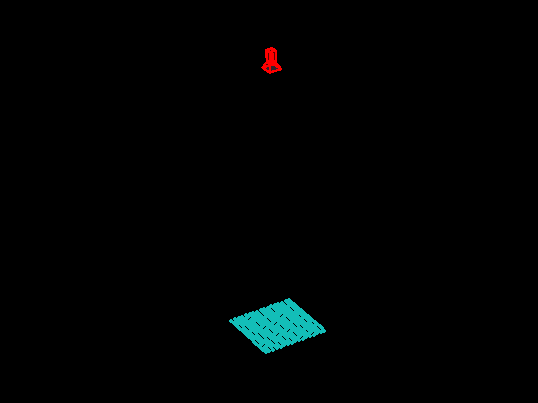

camPose = extr2pose(camExtrinsics);
figure
plotCamera(AbsolutePose=camPose,Size=20);
hold on
pcshow([worldPoints,zeros(size(worldPoints,1),1)], ...
  VerticalAxisDir="down",MarkerSize=40);
hold off

*Copyright 2022 The MathWorks, Inc.*

msg_1.Data = 'referenced'

msg_1 =   ROS String message with properties:

    MessageType: 'std_msgs/String'
           Data: 'referenced'

  Use showdetails to show the contents of the message


send(pub_1, msg_1)

## *Berechnung Punktkoordinaten auf Tisch*

*Berechnung Umrechnungsfaktor Pixel in mm*

disp('Calculate Point Coordinates on the Table')

Calculate Point Coordinates on the Table



% Umrechnungsfaktoren Bildpixel in mm

pix_mmX = ((imagePoints(272,1)-imagePoints(1,1))/(squareSize*(boardSize(1,1)-2)));
pix_mmY = ((imagePoints(1,2)-imagePoints(272,2))/(squareSize*(boardSize(1,2)-2)));

Berechne Verschiebung Schachbrett zu Pixelursprung

[imagePointsMinVal,imagePointsMin] = mink(imagePoints, 1);  % Ermitteln der oberen linken Schachbrettecke
imagePointsMinVal                                           %Pixel Koordinaten oberes linkes Element

imagePointsMinVal =   550.8090  271.8968


Bild von Kamera aufnehmen

disp('Take a Color Picture from the Camera for finding a Circle')

Take a Color Picture from the Camera for finding a Circle



% übernommen aus IntelRealsense Repository 

% Make Pipeline object to manage streaming
pipe = realsense.pipeline();

% Start streaming on an arbitrary camera with default settings
profile = pipe.start();

% Get streaming device's name
dev = profile.get_device();
name = dev.get_info(realsense.camera_info.name);

% Get frames. We discard the first couple to allow
% the camera time to settle
for i = 1:5
    fs = pipe.wait_for_frames();
end

% Stop streaming
pipe.stop();

color_frame = fs.get_color_frame();
color_data = color_frame.get_data();
color_img = permute(reshape(color_data',[3,color_frame.get_width(),color_frame.get_height()]),[3 2 1]);
[color_img_corr,newOrigin] = undistortImage(color_img,intrinsics,OutputView="full");

Kreise ausmessen

%disp('Define a Cirle in the Image')

Define a Cirle in the Image


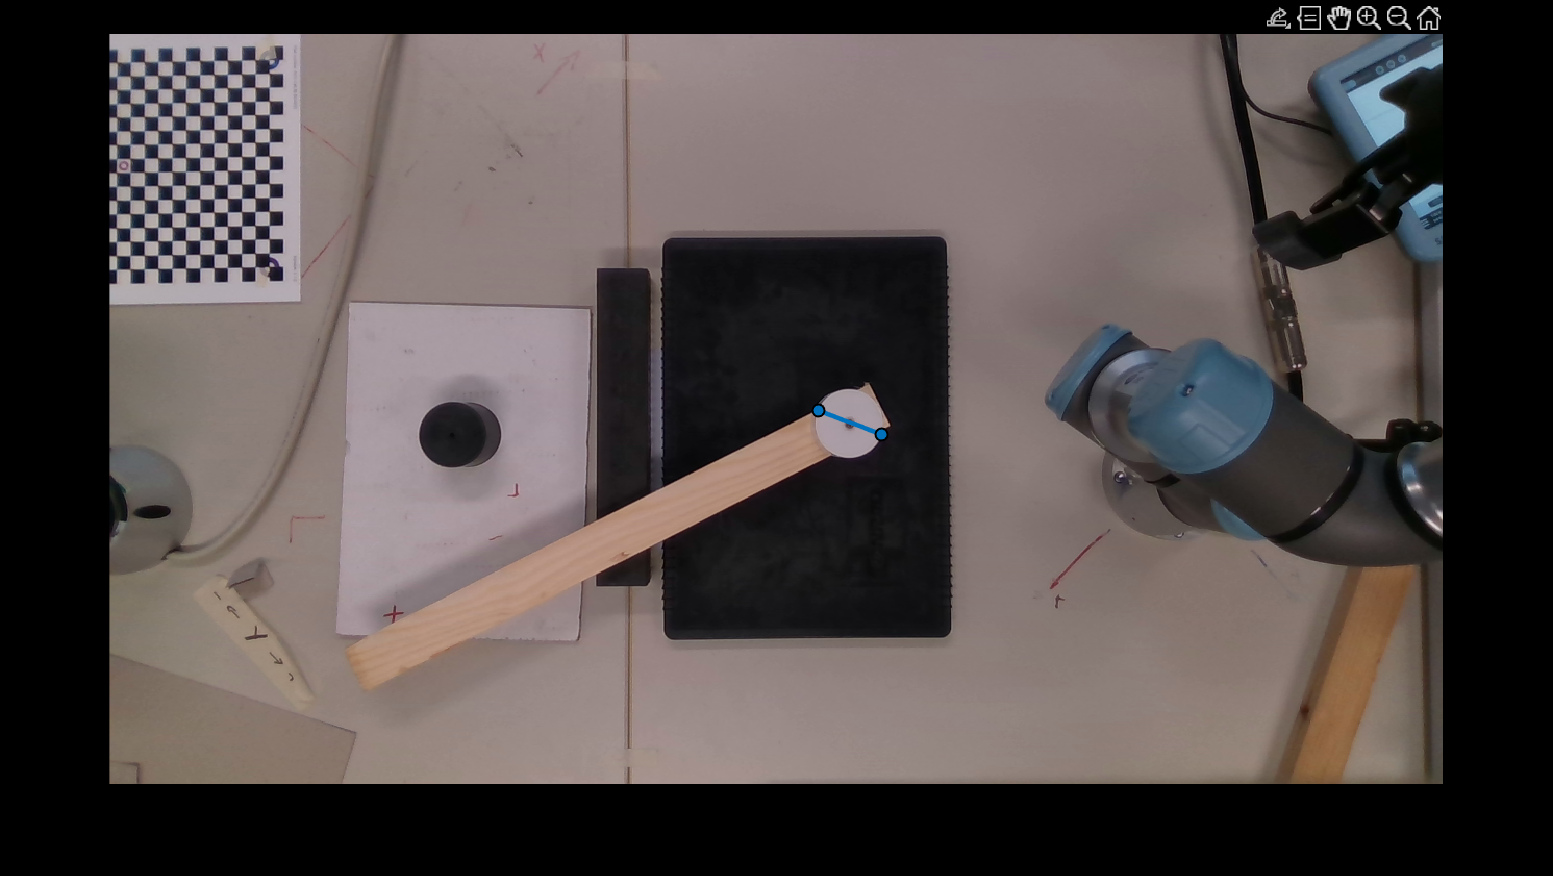


%rgb = color_img_corr;
%imshow(rgb)
%d = drawline;

%pos = d.Position;
%diffPos = diff(pos);
%diameter = hypot(diffPos(1),diffPos(2))

diameter = 64.7235

Finde Kreise

disp('Find Circles in the Image')

Find Circles in the Image



diameter = 61;
[centers, radii, metric] = imfindcircles(rgb,[round((diameter/2)-10) round((diameter/2)+10)],ObjectPolarity="bright") % ggf. Eingabeaufforderung

centers =   710.6329  374.4907


radii = 33.1524

metric = 0.2533

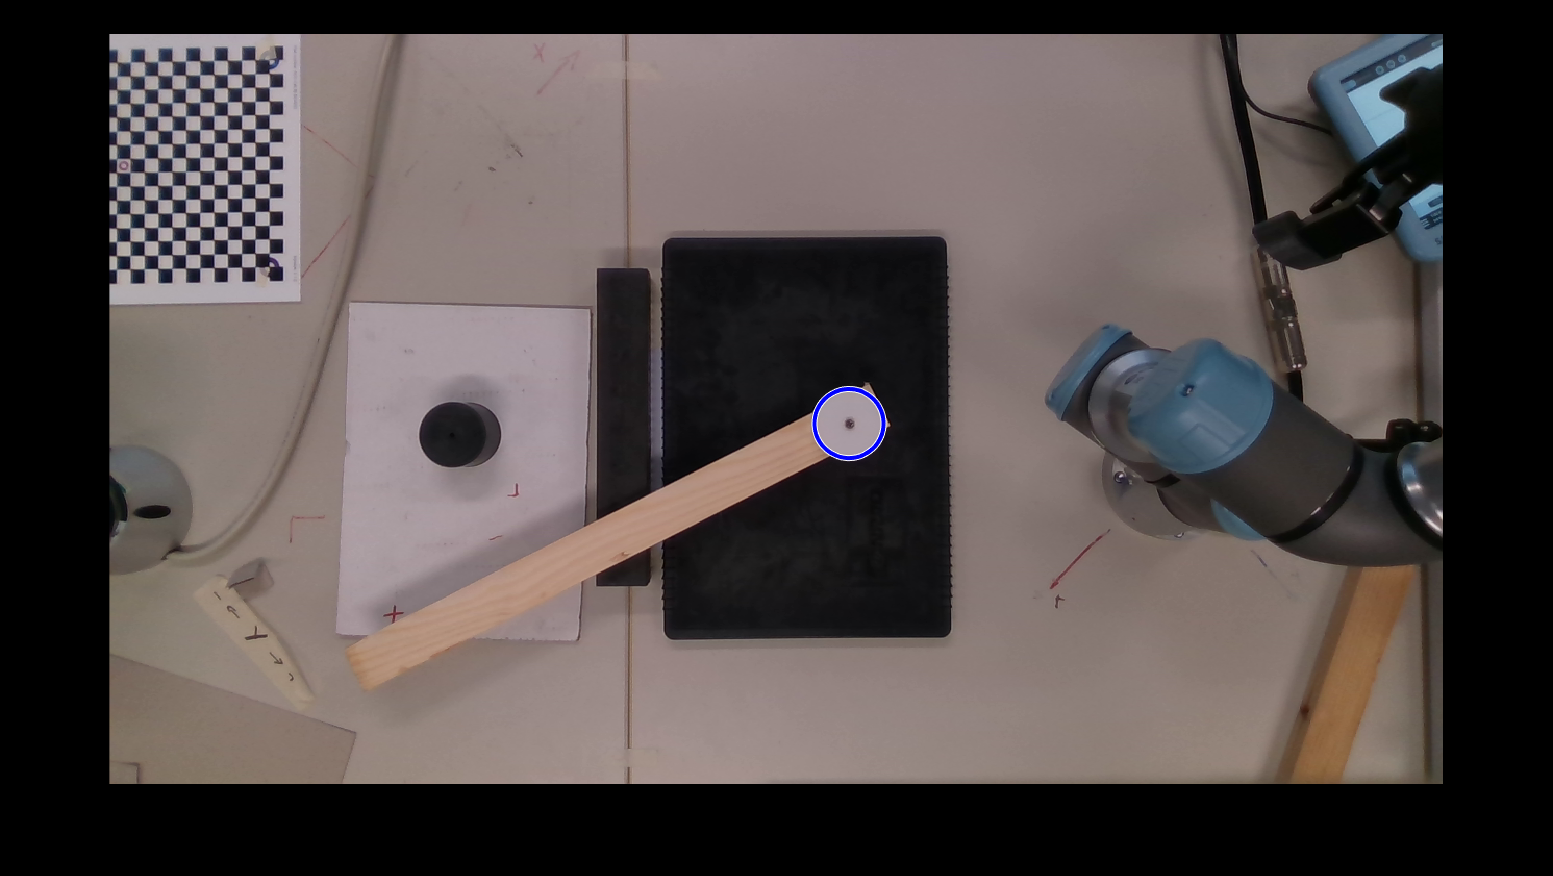

imshow(rgb)
%imshow(color_img_corr)
viscircles(centers, radii,'EdgeColor','b');


% Berechne Mittelpunktkoordinaten des Objektes

coord = centers - imagePointsMinVal % [pixel]

coord =   159.8239  102.5939


imageCoordinates = [  ];
imageCoordinates(1, 1) = coord(1, 1) * pix_mmX  % [mm]

imageCoordinates = 150.1256

imageCoordinates(1, 2) = coord(1, 2) * pix_mmY  % [mm]

imageCoordinates =   150.1256   97.6368



msg_1.Data = 'detected'

msg_1 =   ROS String message with properties:

    MessageType: 'std_msgs/String'
           Data: 'detected'

  Use showdetails to show the contents of the message


send(pub_1, msg_1)
pause(1)

Transformation der Schachbrettkoordinaten auf Roboterkoordinaten

zCoord = 80;
% zCoord = 38;
ObjectCoord = [imageCoordinates(1,1); imageCoordinates(1,2); zCoord]

ObjectCoord =   150.1256
   97.6368
   80.0000


alpha = -46;  % [deg] Drehung um Z-Achse
A = [cosd(alpha), -sind(alpha), 0; 
    sind(alpha), cosd(alpha), 0;
    0, 0, 1]; % Rotationsmatrix um Z-Achse
b = [470.0;164.0;0.0]; % Translationsvektor, Verschiebung um b
robCoord = A*(ObjectCoord - b)

robCoord =  -269.9411
  183.9987
   80.0000


robCoord_switched = [robCoord(2,1);robCoord(1,1);robCoord(3,1)]

robCoord_switched =   183.9987
 -269.9411
   80.0000


robCoord_switched = robCoord_switched * 1/1000

robCoord_switched =     0.1840
   -0.2699
    0.0800


% robCoord = ObjectCoord - b

msg_2.X = robCoord_switched(1,1);
msg_2.Y = robCoord_switched(2,1);
msg_2.Z = robCoord_switched(3,1);
send(pub_2, msg_2)